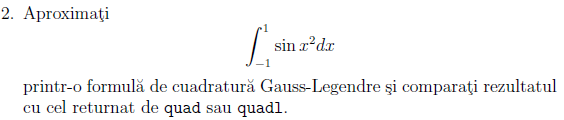

f=@(x) sin(x.^2)

f = function_handle with value:
    @(x)sin(x.^2)


%[x, w] = GaussLegendre(12);
[x, w] = Gauss('Legendre', 12);
%x
%w = w'
%[x, w] = lgwt(6, -1, 1)
%fvector = []
%for v = x
%    fvector = [fvector f(v)];
%end

myResult = getResult(x, w, f)

myResult =    0.620536603446761


matlabQuad = quad(f, -1, 1)

matlabQuad =    0.620536651065556


matlabQuadl = quadl(f, -1, 1)

matlabQuadl =    0.620536603447201


%f=@(x) (exp(1).^(-x.^2)).*sin(x)
f=@(x) exp(-x.^2).* sin(x);
format long

%[x, w] = GaussHermite(30);
[x, w] = Gauss('Hermite', 30);

rezSin = getResult(x, w , f);

f=@(x) exp(-x.^2).* cos(x);
%f=@(x) (exp(1).^(-x.^2)).*cos(x)
format long
[x, w] = Gauss('Hermite', 30);
rezCos = getResult(x, w, f);
rezSin

rezSin =     -5.104456986172672e-16


rezCos

rezCos =    1.106045844146105
